% Connect to the webcam.
cam = webcam(1);

cam =   webcam with properties:

                     Name: 'Integrated Camera'
     AvailableResolutions: {'1280x720'  '960x540'  '848x480'  '640x480'  '640x360'  '424x240'  '352x288'  '320x240'  '320x180'}
               Resolution: '1280x720'
             ExposureMode: 'auto'
                Sharpness: 3
                 Exposure: -6
                      Hue: 0
               Saturation: 64
             WhiteBalance: 4600
               Brightness: 128
                      Pan: 0
                    Gamma: 120
                     Tilt: 0
                 Contrast: 32
         WhiteBalanceMode: 'auto'
              ColorEnable: 1
    BacklightCompensation: 1
          ColorEnableMode: 'manual'
                     Zoom: 100
                     Roll: 0


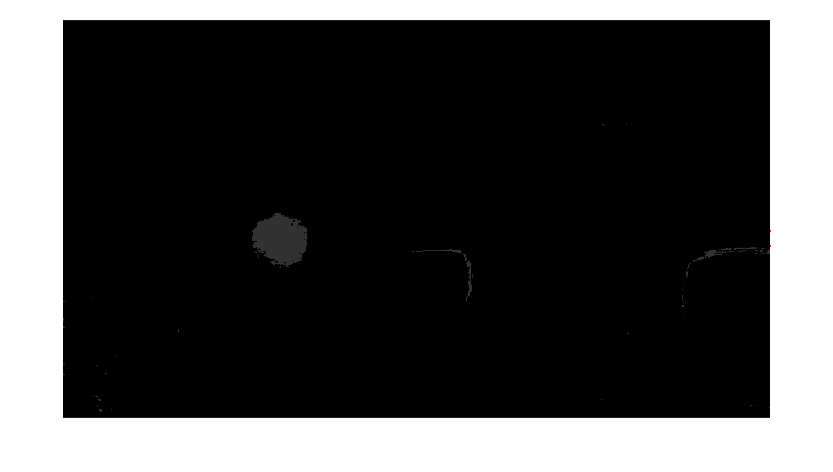



% read the input image
img = snapshot(cam);

% Display the frame in a figure window.

image(img);

% Extract green components
R = img(:,:,1);
G = img(:,:,2);
B = img(:,:,3);

% Only green:

green = G-0.5*R-0.5*B;

green(green > 12) = 50;
green(green < 12) = 0;

%binaryImage = gray_img <= 50;

imshow(green)


[centers,radii] = imfindcircles(green,[10 500],"ObjectPolarity","bright", ...
    "Sensitivity",0.94, "Method","TwoStage")

centers = 1.0e+03 *

    0.3636    0.4064
    0.4234    0.3808
    0.3944    0.3679
    0.4256    0.4085
    0.4097    0.4292
    1.1891    0.4377
    1.1902    0.4065
    1.2432    0.4241
    0.7274    0.4853
    1.1495    0.4464


radii =     13
    15
    18
    16
    16
    15
    14
    14
    14
    13


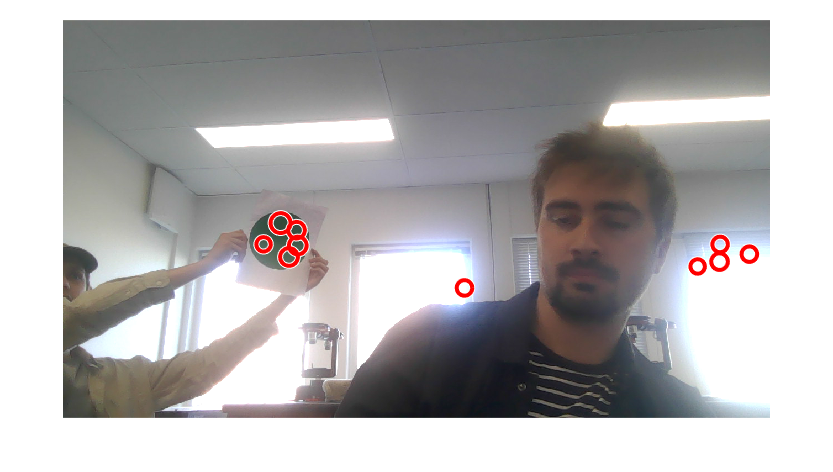

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties



% Display the original image with green circles overlaid
figure;
imshow(img)
hold on;
viscircles(centers,radii,'Color','r')

cam = webcam(1);


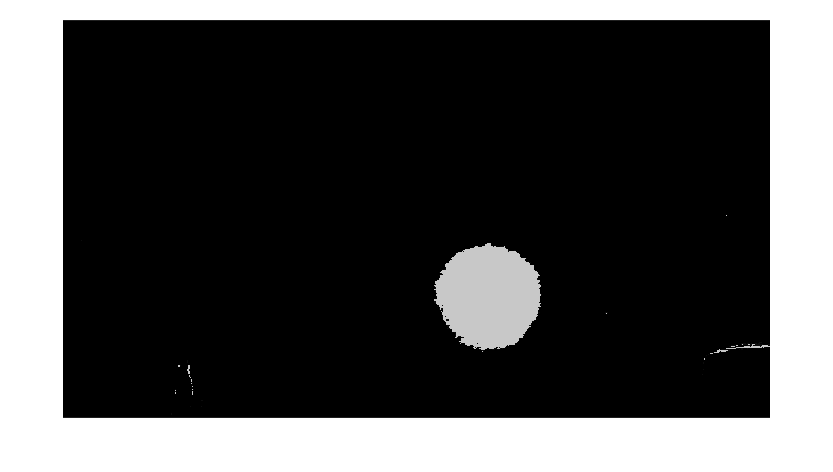

% read the input image
%img = snapshot(cam);

% Display the frame in a figure window.

image(img);

% Extract green components
R = img(:,:,1);
G = img(:,:,2);
B = img(:,:,3);

% Only green:

green = G-0.5*R-0.5*B;

green(green > 12) = 200;
green(green < 12) = 0;

%binaryImage = gray_img <= 50;

imshow(green)


val = sum(sum(green == 50))

val = 0



[centers,radii] = imfindcircles(green,[40 500],"ObjectPolarity","bright", ...
    "Sensitivity",0.98, "Method","TwoStage")

centers =   815.1689  509.6338
  813.9803  469.8999
  749.4407  516.1237


radii =     52
    44
    65


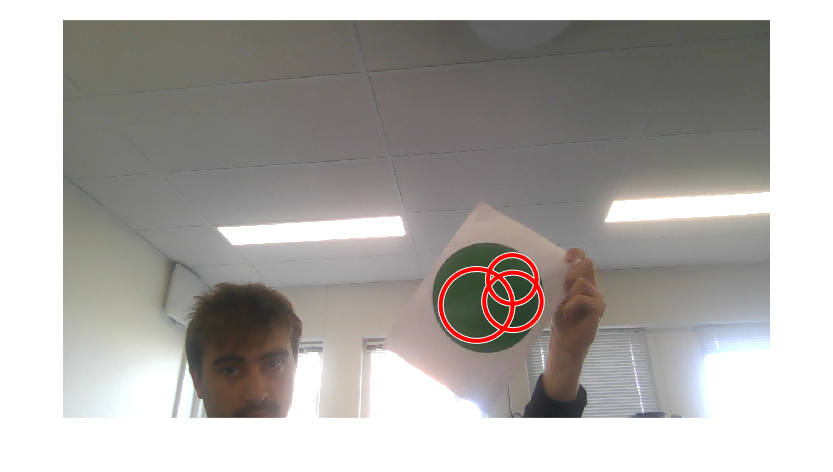

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties



% Display the original image with green circles overlaid
figure;
imshow(img)
hold on;
viscircles(centers,radii,'Color','r')

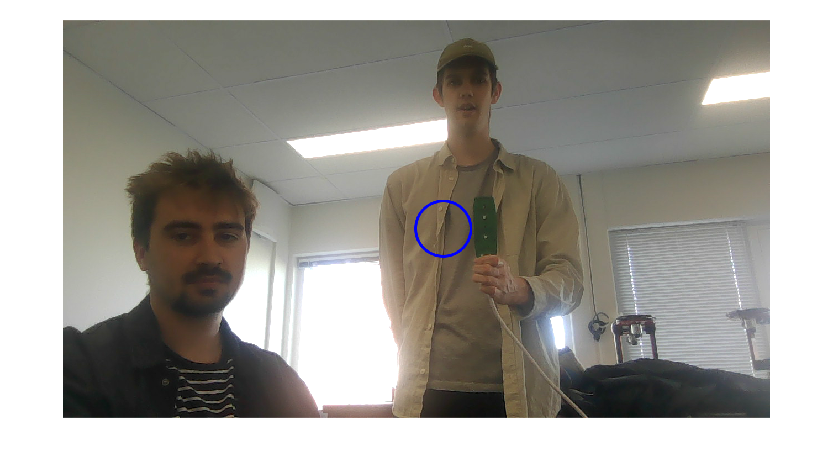


% use regionprops to get properties of the connected components in the image
props = regionprops(green, 'Area', 'Centroid');

% find the largest circle
max_area = 1000;
max_circle = [];
for i = 1:numel(props)
    if props(i).Area > max_area
        max_area = props(i).Area;
        max_circle = props(i).Centroid;
    end
end

% draw a circle around the largest green object
output_img = insertShape(img, 'circle', [max_circle 50], 'LineWidth', 5, 'Color', 'blue');

% display the output image
imshow(output_img);

max(max(green))

ans = uint8
0